T = readtable('TestDataLog.xlsx');
data = table2struct(T);
acc = [data.AccX; data.AccY; data.AccZ]';
gyro = [data.GyroX; data.GyroY; data.GyroZ]';
mag = [data.MagX; data.MagY; data.MagZ]';

% check data was recieved consistently

diffA = diff([data.AccTick])';
diffG = diff([data.GyroTick])';
diffM = diff([data.MagTick])';
mean([diffA; diffG; diffM])

ans = 120.8482

max([diffA; diffG; diffM])

ans = 161

period = mode([diffA; diffG; diffM])

period = 120

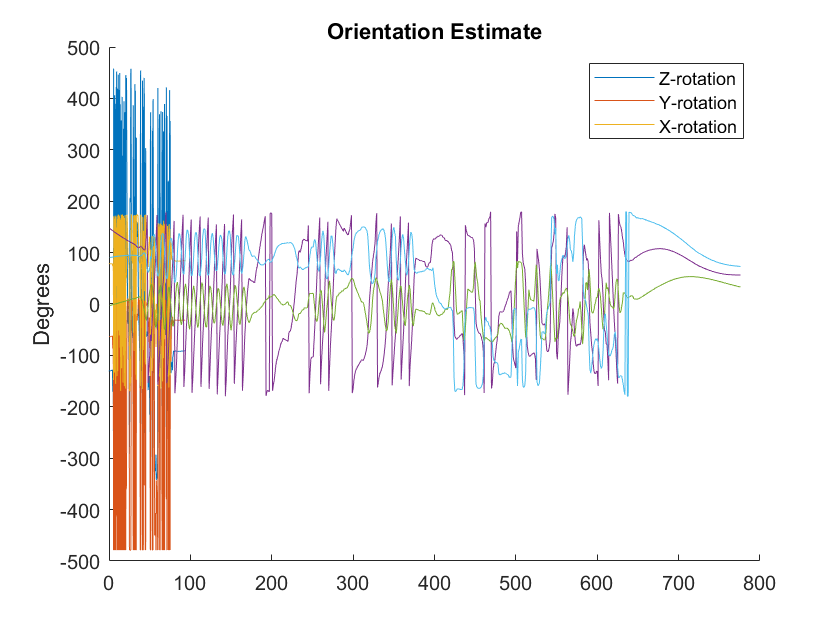

fs = (1.0*1000)/period;

fuse = complementaryFilter('SampleRate', fs);

q = fuse(acc, gyro, mag);
plot(eulerd( q, 'ZYX', 'frame'));
title('Orientation Estimate');
legend('Z-rotation', 'Y-rotation', 'X-rotation');
ylabel('Degrees');

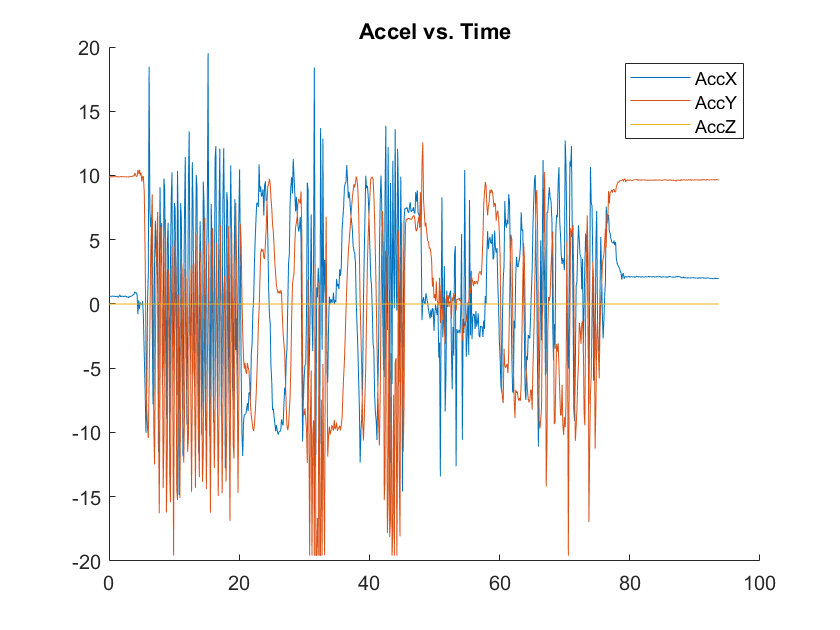


% viewer = HelperOrientationViewer;
% cfilt = complementaryFilter('SampleRate', fs);
% for ii=1:size(acc,1)
%     qahrs = cfilt(acc(ii,:), gyro(ii,:), mag(ii,:));
%     viewer(qahrs);
%     pause(0.1);
% end



% plot each axis
figure;
hold on;
t = [data.AccTick];
tA = (t-t(1))/1000.0;
plot(tA, [data.AccX]);
plot(tA, [data.AccY]);
plot(tA, [data.AccZ]);
title('Accel vs. Time');
legend('AccX', 'AccY', 'AccZ')


RPM_conversion = 30.0/pi;
figure;
hold on;
t=[data.GyroTick]

t =      5911188     5911308     5911428     5911548     5911669     5911788     5911908     5912028     5912148     5912268     5912389     5912508     5912628     5912748     5912868     5912988     5913108     5913228     5913348     5913468     5913588     5913708     5913828     5913948     5914068     5914188     5914309     5914428     5914548     5914667     5914788     5914908     5915028     5915148     5915269     5915388     5915508     5915627     5915748     5915868     5915988     5916108     5916229     5916348     5916468     5916614     5916748     5916868     5916988     5917108


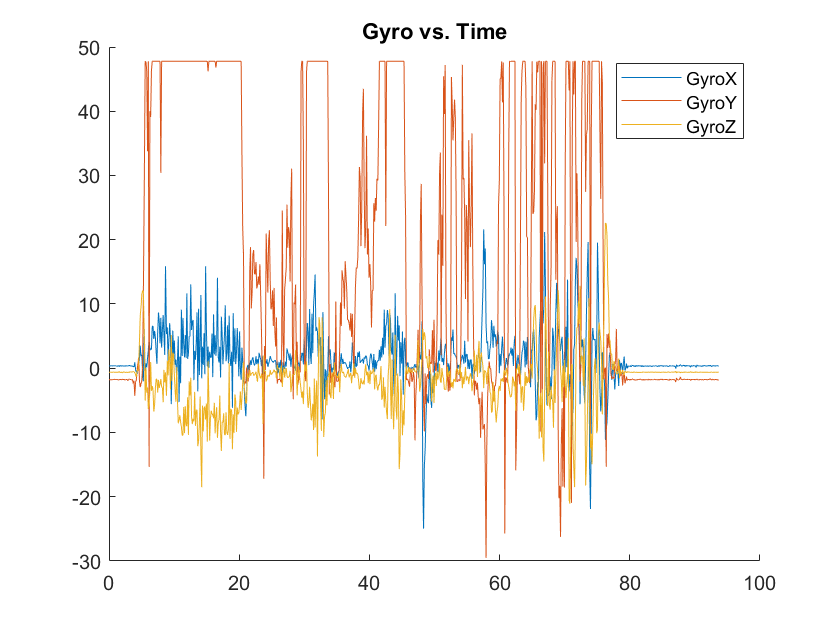

tG = (t-t(1))/1000.0;
plot(tG, [data.GyroX]*RPM_conversion);
plot(tG, [data.GyroY]*RPM_conversion);
plot(tG, [data.GyroZ]*RPM_conversion);
title('Gyro vs. Time');
legend('GyroX', 'GyroY', 'GyroZ')

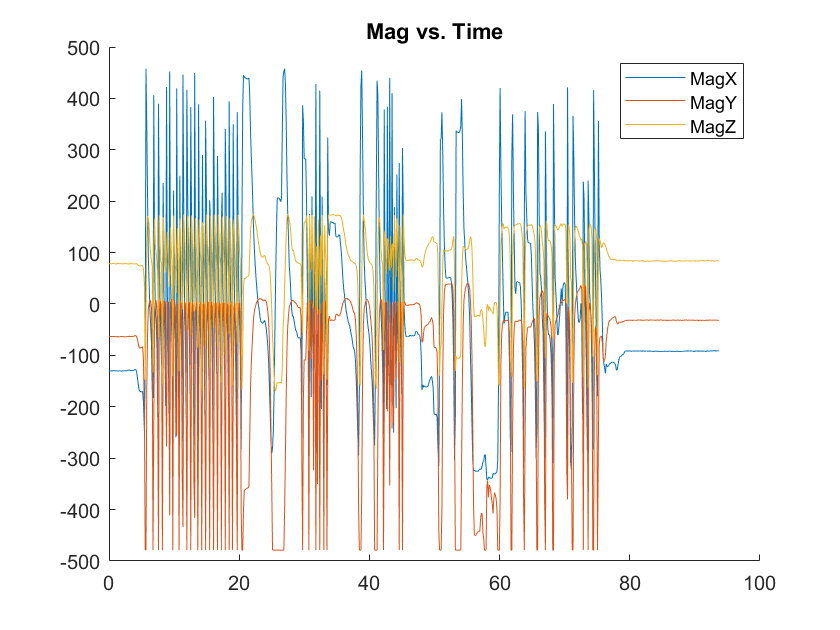


figure;
hold on;
t = [data.MagTick];
tM = (t-t(1))/1000.0;
plot(tM, [data.MagX]);
plot(tM, [data.MagY]);
plot(tM, [data.MagZ]);
title('Mag vs. Time');
legend('MagX', 'MagY', 'MagZ')